# Model Testing and Validation

## Methods of testing

Consider a hypothetical data set with information on 1000 patients. 

- **Hold out validation:** build a model from the first 500 patients and test on the next 500.

- **Ten fold cross validation:**  build a model from the first 900 patients and test on the next 100, then build a model using data from patients 101-1000 and test on the first 100, and so on until you cover the whole data set.

- **Re-substitution (weakest method)**: train on data from all 1000 patients and test on the same data set.

- **Independent validation (strongest): **use data from a different study to test the model.

## Metrics for evaluating accuracy

Continuous response data (e.g. levels of blood glucose)

- **Pearson's Correlation:** measures the strength and direction of a linear relationship between two variables.

- **Rank Correlation:** measures the strength and direction of a monotonic relationship between two variables.

- **Root Mean Square Error (RMSE): **measures the standard deviation of the residuals. Residuals represent the difference between predicted values and observed values. 


$$\mathrm{RMSE}=\sqrt{\frac{\left({\sum_{i=1}^n \left({\hat{y} }_i -y_i \right)}^2 \right)}{n}}$$


Discrete data sets (e.g. Normal vs Diabetes)

- **Accuracy:** the ratio of correct predictions to the total observations.

- **Precision:** the ratio of true positives to the total predicted positives.

- **Recall:** the ratio of true positives to the total actual positives. Also known as sensitivity. 

There is no single metric that gives an overall picture of accuracy. It is necessary to use a range of metrics to get a holistic picture.

## Multinomial linear regression model

Consider BMI to be a function of age, sex, glucose, cholesterol, and systolic blood pressure. How can we use these variables to determine BMI?

Recall from last lecture that we can use the `fitlm` function to create a linear regression model. Start by reading in the Framingham data set and extracting the explanatory and response variables into a new table. (Hint: When using `fitlm` with a table, the last column in the table is assumed to be the response variable.) 

fram = readtable("../frmgham.xls");
fram_revised = fram(:,["AGE","SEX","GLUCOSE","TOTCHOL","SYSBP","BMI"]);

Note that we do not need to remove observations with missing data as the `fitlm` function does this for us. Now create the linear regression model. 

BMI_model = fitlm(fram_revised)

BMI_model = Linear regression model:
    BMI ~ 1 + AGE + SEX + GLUCOSE + TOTCHOL + SYSBP

Estimated Coefficients:
                   Estimate         SE         tStat       pValue   
                   _________    __________    _______    ___________

    (Intercept)       19.817       0.33998      58.29              0
    AGE            -0.027034      0.004449    -6.0765     1.2734e-09
    SEX             -0.77047      0.078443    -9.8219     1.1467e-22
    GLUCOSE        0.0077801     0.0015712     4.9518      7.474e-07
    TOTCHOL        0.0052678    0.00087394     6.0276     1.7225e-09
    SYSBP           0.049713     0.0018665     26.634    4.6066e-151


Number of observations: 10021, Error degrees of freedom: 10015
Root Mean Squared Error: 3.86


The linear regression model is represented by the following equation:

$Y=19\ldotp 817-0\ldotp 027*\mathrm{AGE}-0\ldotp 77*\mathrm{SEX}+0\ldotp 008*\mathrm{GLUC}+0\ldotp 005*\mathrm{TOTCHOL}+0\ldotp 05*\mathrm{SYSBP}$. 

This model uses all of the observations in the explanatory data set to create a best fit line for BMI. 

## Testing regression models using hold out validation

When using the hold out validation method, a portion of the data is used as the training set while the rest is held out to be used as the testing test. 

We have created a custom function for generating the training and test sets called `trainTestSplit`. Use the `open` function to view the script for `trainTestSplit`. 

open trainTestSplit.mlx

The `trainTestSplit` function randomly assigns rows from our data set into the training and test sets, whose sizes are determined by our input for the `trainSize`. 

We will use `trainTestSplit` to perform hold out validation by training on 2/3 of the data set and testing on the remaining 1/3. For this method, it will be helpful to remove the observations with missing data, as well as consolidate the explanatory and response features into new variables (*X* and *Y*, respectively).

Create the X and Y data sets and use them as inputs for the `trainTestSplit` function.

fram_noNaN = rmmissing(fram_revised);
X = fram_noNaN{:,{'AGE','SEX','GLUCOSE','TOTCHOL','SYSBP'}};
Y = fram_noNaN.BMI;
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X,Y,0.667);

Now that the data sets have been divided, we can use the `fitlm `function again to create a new linear regression model with the training data set. 

model = fitlm(Xtrain,Ytrain)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)       19.735      0.41916     47.082             0
    x1              -0.02542    0.0054756    -4.6424    3.5094e-06
    x2              -0.83959     0.096125    -8.7343      3.06e-18
    x3             0.0095202    0.0019709     4.8303    1.3935e-06
    x4             0.0058866    0.0010724     5.4892    4.1866e-08
    x5              0.048343    0.0023249     20.793    4.2209e-93


Number of observations: 6684, Error degrees of freedom: 6678
Root Mean Squared Error: 3.86
R-squared: 0.0852,  Adjusted R-Squared:

What is the correlation between `Xtrain` and `Ytrain`? Recall that the `corr `function will output an array containing the correlation coefficients between BMI and each of the predictor variables.

corr(Xtrain,Ytrain)

ans =     0.0616
   -0.0838
    0.0920
    0.0851
    0.2592


## Evaluating accuracy in the test set

The model's predicted values for `Y` can be calculated using the `predict` function. Use this function to evaluate the model given the `Xtest` data set.

Ypred = predict(model,Xtest);

How do the values in `Ypred` compare to the actual BMI values in `Ytest`? Use the `scatter` function to compare.

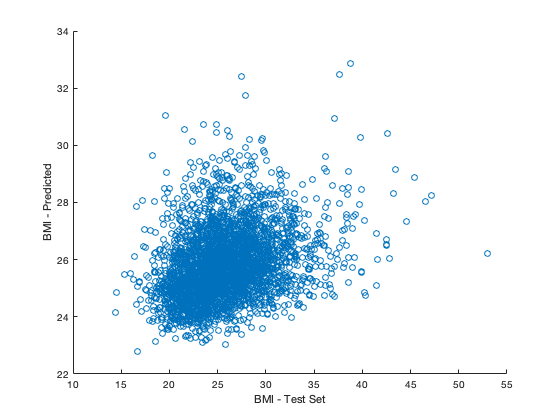

scatter(Ytest,Ypred)
xlabel('BMI - Test Set')
ylabel('BMI - Predicted')

How strong is the linear relationship that is displayed in the scatterplot?

corr(Ytest,Ypred)

ans = 0.2969

There are several other parameters that we can calculate to examine the model.

#### Percent Error - measures the difference between estimated and actual values

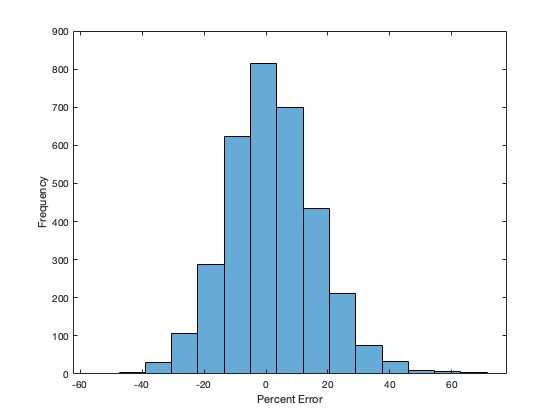

percent_error = (Ypred-Ytest) ./ Ytest * 100;
histogram(percent_error,15)
xlabel('Percent Error')
ylabel('Frequency')

#### Percent Average Error

percent_avg_error = mean(abs(percent_error))

percent_avg_error = 11.4423

#### Root Mean Square Error (RMSE) - measures the standard deviation of the residuals

RMSE = sqrt(mean((Ypred-Ytest).^2))

RMSE = 3.8577

RMSE is sensitive to large errors because the squaring process gives disproportionate weight to very large errors. Further, the RMSE can only be compared between models whose errors are measured in the same units. There is no absolute criterion for a "good" value of RMSE; it depends on the units in which the variable is measured and on the degree of predictive accuracy.

### Testing Using Cross Validation

We will now repeat the previous analysis using five fold cross validation. For this analysis, the data set will be broken into five groups of equal size, called folds. We will train the model wth 80% of the data set and test the model with the remaining 20%. This process will be repeated five times so that a model is created for each test set. 

Note that if there is any sort of ordering to the data, we cannot simply split the first 80% into the training set and the last 20% into the test set. It is better to populate the training and test sets by randomly ordering or shuffling the data set first. There are a number of ways to randomize data in MATLAB. One method is shown below:

shuffled = fram_noNaN(randperm(size(fram_noNaN,1)),:);

There are several functions in MATLAB built for generating training and test sets, and they often shuffle the data internally. One of these functions is `crossvalind`. The function requires inputs for the cross validation method (`'kfold'` in our case), the number of observations, and the number of folds (`k`). The output contains a randomized array of indices (varying from 1 to `k`) which are assigned to each row in the data set and create folds of approximately equal size.

Create an array which contains randomized indices for all of the rows in our data set.

indices = crossvalind('kfold',size(fram_noNaN,1),5)

indices =      4
     5
     4
     1
     2
     1
     4
     1
     2
     5


We can see that each row in the `indices` array contains a value between 1 and 5, linking that row to a certain fold. These indices allow us to easily separate the data into the training and test sets for the five fold cross validation. Confirm that the new data sets are approximately the same size.

sum(indices==1)

ans = 2004

sum(indices==2)

ans = 2004

sum(indices==3)

ans = 2005

sum(indices==4)

ans = 2004

sum(indices==5)

ans = 2004

Now that we have a way to break the data into five folds, we can use similar steps as in the hold out validation test to analyze the statistical relationship between `Ypred` and `Ytest`. Because five separate models must be created, a **for loop** will be used.

First, initialize the RMSE, correlation and average error variables. These parameters will be calculated for each of the five models.

RMSE_kfold = zeros(5,1);
corr_kfold = zeros(5,1);
avg_error = zeros(5,1);

Initializing variables prior to the for loop helps improve the speed of the script. Instead of having to reallocate memory each iteration for the growing matrix, the matrix zeros are simply replaced with the new values. However, it is important that the matrix is initialized to the correct size.

The for loop will use the indices to determine the training and test sets for each iteration. It will then calculate the correlation, RMSE and average percent error values as we did previously, and store them in the matrices that we initiliazed. For example, in the first iteration, every row with an assigned index of 1 is treated as the test set, while the remaining data is assigned to the training set. In the second iteration, rows with an index of 2 are used for the test set, and those with an index of 1, 3, 4 or 5 comprise the training set. 

% Run through loop 5 times and assign iteration number to i. Identify rows
% in indices equal to i and assign to test; assign remaining rows to train.
for i = 1:5   
    test = (indices == i);   
    train = ~test;   
    
    % Extract train rows from X and Y. Create linear model with train data.
    Xtrain = X(train,:);    
    Ytrain = Y(train,:);   
    model = fitlm(Xtrain,Ytrain);  
    
    %Extract test rows from X and Y 
    Xtest = X(test,:);   
    Ytest = Y(test,:);   
    
    % Predict Y values from model. Calculate stat parameters and assign
    % to index i of variables
    Ypred = predict(model,Xtest);   
    corr_kfold(i) = corr(Ytest,Ypred);   
    RMSE_kfold(i) = sqrt(mean((Ypred-Ytest).^2));   
    avg_error(i) = mean(abs(Ypred-Ytest)./Ytest*100);
end

Because there are five values in each of the output arrays, use the `mean` function to view the correlation, RMSE and average percent error values.

mean(corr_kfold)

ans = 0.2916

mean(RMSE_kfold)

ans = 3.8629

mean(abs(avg_error))

ans = 11.3993

## Evaluating discrete data sets using hold out validation

Similar methods can be used to evaluate discrete data sets, where the data can only take on certain values. An example would be classifying patients with diabetes versus those without diabetes. The values can only be one of two numbers: 0 (non-diabetic) or 1 (diabetic).

How well can we predict diabetes from the patients' glucose levels? Since we are using the hold out method, we can incorporate the `trainTestSplit` function again. This time, create a training set with 80% of the data set. 

fram_discrete = rmmissing([fram.GLUCOSE, fram.DIABETES]);
gluc = fram_discrete(:,1);
diab = fram_discrete(:,2);
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(gluc,diab,0.8);

Recall from last lecture that we used the `mnrfit` function for analyzing discrete categorical data. The response variable, diabetes, must first be converted into a categorical array with the `categorical` function. 

Ytrain = categorical(Ytrain);

The `Ytrain` variable contains two categories: non-diabetic (0) and diabetic (1). The last category, in this case diabetic, is always used as the reference category for the `mnrfit` function. The logistic regression model will tell us the relative log odds of being non-diabetic versus diabetic. Create the model using `Xtrain` and `Ytrain` and then print the regression coefficients. 

[b,~,stats] = mnrfit(Xtrain,Ytrain);
b

b =     8.6356
   -0.0577


The first term in `b` is the intercept term of the relative risk model and the second term is the coefficient for glucose levels. The resulting equation is: $\mathrm{ln}\left(\frac{\pi_{\mathrm{normal}} }{\pi_{\mathrm{diabetic}} }\right)=8\ldotp 6748-0\ldotp 0577X_1$.

The relative log odds of being non-diabetic versus diabetic decreases 0.0565 times with a one-unit increase in $X_1$, assuming all else is equal. Here $X_1$ is our only predictor variable, glucose. While this does not seem like a strong relationship, the model makes sense. Diabetic patients typically have higher glucose levels, so for every unit increase in glucose, there is a lesser chance that the patient is non-diabetic. 

The `mnrfit` function also outputs several other statistical parameters, such as the *p-*value for each of the mdoel parameters.

stats.p

ans = 	1.0e+-117 *

    0.0000
    0.2078


The *p-*value for glucose is magnitudes below the accepted value of 0.05, meaning the measure of glucose levels is significant to the relative risk of being non-diabetic versus diabetic. 

## Estimating model accuracy in test data

The model accuracy can be evaluated using the test sets that we created, along with the `mnrval` function. Recall that this function returns the predicted probabilities for the logistic regression model given certain values for the predictor variables, which come from the predictor test set.

probability = mnrval(b,Xtest);

Let's look at the first five rows of the predicted diabetes classifications.

probability(1:5,:)

ans =     0.9708    0.0292
    0.9491    0.0509
    0.9803    0.0197
    0.9767    0.0233
    0.9791    0.0209


The left column shows the probability, based on our model, that the patient is non-diabetic. The right colum shows the probabilty that they are diabetic. 

In order to compare the predicted values to the test values, round the predicted values to the nearest integer (0 or 1). The model accuracy can then be determined by checking how many rows in the predicted and test sets match. We want to use the second column from the `probability` matrix because in that case, a 0 will indicate non-diabetic and 1 will indicate diabetic, which is the same system as the test data set.

Ypred_round = round(probability);
accuracy = sum(Ypred_round(:,2) == Ytest)/length(Ypred_round) 

accuracy = 0.9705

## Hold out validation with multiple predictors

We will now repeat the hold out validation test, but this time we will use BMI, glucose and cholesterol to predict diabetes. What is the equation for this model and which variable has the greatest effect on predicting BMI? Also, which variables are statistically significant?

fram_discrete_2 = rmmissing([fram.GLUCOSE, fram.BMI, fram.TOTCHOL, fram.DIABETES]);
X = fram_discrete_2(:,1:3);
Y = fram_discrete_2(:,4);
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X,Y,0.8);
Ytrain = categorical(Ytrain);
[b,~,stats] = mnrfit(Xtrain,Ytrain);
b

b =    10.9172
   -0.0598
   -0.0701
   -0.0004


stats.p

ans =     0.0000
    0.0000
    0.0000
    0.7921


Based on the results, the model's equation should look similar to this: $\mathrm{ln}\left(\frac{\pi_{\mathrm{normal}} }{\pi_{\mathrm{diabetic}} }\right)=10\ldotp 6125-0\ldotp 0563X_1 -0\ldotp 0741X_2 -0\ldotp 0004X_3$. Our model suggests that BMI has the greatest impact towards being diabetic or non-diabetic. Based on the *p-*values, we would reject the null hypothesis for glucose and BMI, and fail to reject for total cholesterol. 

Next, find the accuracy of the model.

probability = mnrval(b,Xtest); 
Ypred_round = round(probability);
accuracy = sum(Ypred_round(:,2) == Ytest)/length(Ypred_round) 

accuracy = 0.9646

## Example: 10 fold cross validation

We will now use 10 fold cross validation to evaluate our model for diabetes using glucose, BMI and cholesterol. A for loop similar to the one used in the previous example can be used. 

% Assign random indices for each for row in data set
indices = crossvalind('kfold',size(fram_discrete_2,1),10);  

% Initialze output variables
b = zeros(4,10);         
p_values = zeros(4,10);   
accuracy = zeros(1,10);   

% Run through loop 10 times and assign iteration number to i. Identify rows
% in indices equal to i and assign to test; assign remaining rows to train.
for i = 1:10   
    test = (indices == i);   
    train = ~test;   
    
    % Extract training rows from X and Y. Convert Ytrain to categorical.
    Xtrain = X(train,:);   
    Ytrain = Y(train,:);   
    Ytrain = categorical(Ytrain);   
    
    % Create model w/ training sets. Store model coefficients and p values.
    [b(1:4,i),~,stats] = mnrfit(Xtrain,Ytrain);   
    p_values(1:4,i)= stats.p;   
    
    % Extract test rows from X and Y
    Xtest = X(test,:);   
    Ytest = Y(test,:);   
    
    % Calculate probability for each category, round up to nearest integer
    % and calculate accuracy using Ypred and Ytest
    probability = mnrval(b(:,i),Xtest);   
    Ypred_round = round(probability(:,2));    
    accuracy(1,i) = sum(Ypred_round == Ytest)/length(Ypred_round);   
end

We now have the model coefficients, *p-*values and accuracy for each of the ten models. Calculate the mean for each of these values.

b_avg = mean(b,2)  % the 2 tells the function to take the mean of each row

b_avg =    10.6025
   -0.0567
   -0.0670
   -0.0009


p_avg = mean(p_values,2)

p_avg =     0.0000
    0.0000
    0.0000
    0.5093


accuracy_avg = mean(accuracy)

accuracy_avg = 0.9701

We now have a model with the equation of $\mathrm{ln}\left(\frac{\pi_{\mathrm{non}-\mathrm{diabetic}} }{\pi_{\mathrm{diabetic}} }\right)=10\ldotp 599-0\ldotp 0567X_1 -0\ldotp 0670X_2 -0\ldotp 009X_3$Once again, the *p-*values indicate that glucose and BMI are significant to the model, but total cholesterol is not.

## Additional metrics to evaluate accuracy

Confusion matrices are useful tools for evaluating how well a classification model performs. The `confusionchart` function allows us to visually compare the classifications of the predicted and test data sets.

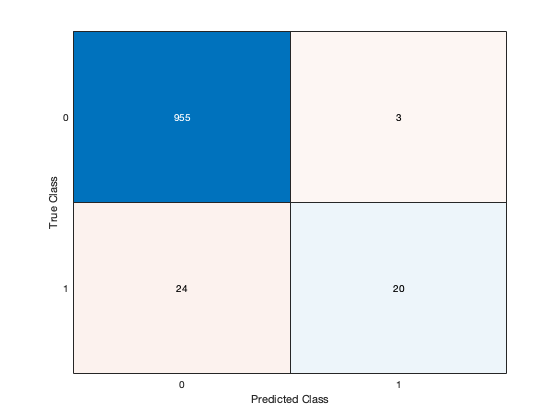

confusionchart(Ytest,Ypred_round);

There are four sections in the confusion matrix:

- **True positive (TP)** - the model predicts TRUE and the actual outcome is TRUE 

- **True negative (TN)** - the model predicts FALSE and the actual outcome is FALSE 

- **False positive (FP)** - the model predicts TRUE and the actual outcome is FALSE 

- **False negative (FN) **- the model predicts FALSE and the actual outcome is TRUE 

Using the values in the confusion matrix or the model variables (`Ypred` and `Ytest`), calculate the following parameters:

- **Precision **- the number of times that the model correctly predicted diabetes over the total number of times that the model predicted diabetes.

precision = sum(Ypred_round==1 & Ytest==1)/sum(Ypred_round==1)

precision = 0.8696

This is equivalent to the following calculation from the confusion matrix: $\mathrm{precision}=\frac{16}{\left(16+2\right)}=0\ldotp 889$

- **Recall **- the number of times the model correctly predicted diabetes over the total number of diabetes cases in the test set. 

recall = sum(Ypred_round==1 & Ytest==1)/sum(Ytest==1)

recall = 0.4545

This is equivalent to the following calculation from the confusion matrix: $\mathrm{recall}=\frac{16}{\left(16+29\right)}=0\ldotp 356$

## Outcome: model testing and validation

Errors arise due to both bad data and bad models

Need to have the right benchmark i.e. what accuracy is good enough?

**Overfitting** - model is too complex

- Solution: simplify the model, get more training data, reduce noise in the data

**Underfitting** - model is too simple

- Solution: add more features to the model, use more complex algorithms

**Confounding variables** - some features are irrelevant

- Solution: start with a strong hypothesis, use unsupervised learning methods to find relevant features,                                 make sure the training data has appropriate features and sample size

A problem can arise when you measure the generalization error multiple times on the test set, and then adapt the model and hyperparameters to produce the best model *for that set. *This means that the model is unlikely to perform as well on new data. A common solution to this problem is to have a second holdout set called the **validation set**, which is used to run a single final test against the test set to get an estimate of the generalization error. 

## Improving data quality by normalization

- Most machine learning algorithms calculate the distance between two data points.

- The range of numeric values can be different between the various feature variables. For example, in the Framingham data set, BMI has a larger value and range than Sex or Education.

- Euclidean distance will be skewed by magnitude and range.

- The range of all features should be normalized so that each feature contributes equally to the distance.

- Scaling and normalization allows us to compare features at the same scale.

## Re-scaling Framingham data set

Re-scaling data can help improve your linear regression model. If the explanatory variables are very different in their magnitudes, it can be difficult to interpret the model coefficients. In the Framingham data set, for example, Age ranges from 32 to 81, while Total Cholesterol ranges from 107 to 696. This difference in magnitude may exaggerate the effect of Total Cholesterol in the model. 

One method for scaling the data is to set all of the predictor means to zero. To do this, the variable's mean is subtracted from each data point and then divided by the standard deviation. 


$$z=\frac{\left(x-\mu \right)}{\sigma }$$


The MATLAB function `zscore` does these calculations for you.

Example: plot normalized BMI vs Glucose

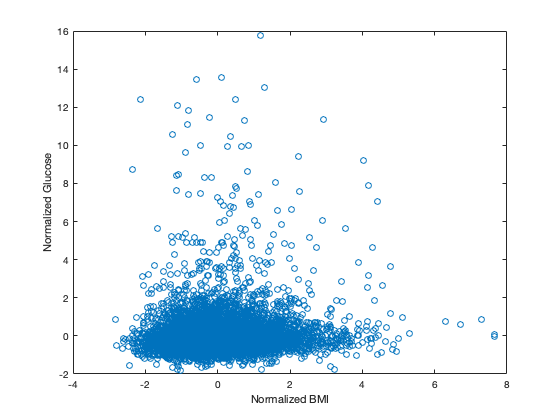

BMI_norm = zscore(fram_noNaN.BMI);
gluc_norm = zscore(fram_noNaN.GLUCOSE);
plot(BMI_norm,gluc_norm,'o')
xlabel('Normalized BMI')
ylabel('Normalized Glucose')

The `pdist` function outputs the Euclidean distance between pairs of observations. We can use this function to see the effects of normalization. Compare the average distance between the BMI and glucose data points before and after normalization.

Y1 = pdist([fram_noNaN.BMI,fram_noNaN.GLUCOSE]); 
mean(Y1)

ans = 21.5268

Y2 = pdist([BMI_norm,gluc_norm]); 
mean(Y2)

ans = 1.5322

We will now revisit our original model which used age, sex, glucose, total cholesterol and systolic blood pressure to predict BMI. Use `gplotmatrix` to create a scatterplot matrix of these normalized variables.

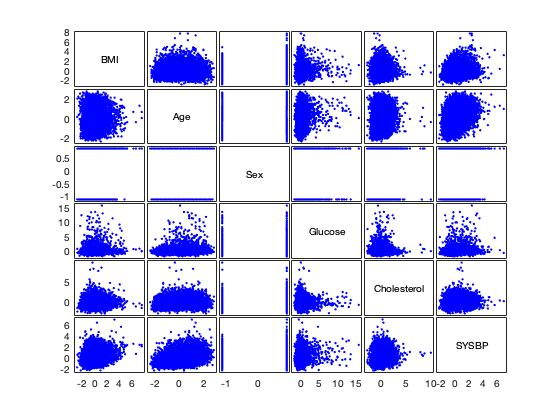

vars = zscore(fram_noNaN{:,{'BMI','AGE','SEX','GLUCOSE','TOTCHOL','SYSBP'}});
var_names = {'BMI', 'Age', 'Sex', 'Glucose', 'Cholesterol', 'SYSBP'};
gplotmatrix(vars,[],[],[],[],[],[],'variable',var_names);

Create a model using the scaled features and compare the regression coefficient values to those of the original model (*BMI_model).*

X_norm = vars(:,2:6);
Y_norm = vars(:,1);
fitlm(X_norm,Y_norm)

ans = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
                    Estimate         SE           tStat         pValue   
                   ___________    _________    ___________    ___________

    (Intercept)    -2.9596e-14    0.0095503    -3.0989e-12              1
    x1               -0.063592     0.010465        -6.0765     1.2734e-09
    x2               -0.094771    0.0096489        -9.8219     1.1467e-22
    x3                 0.04815    0.0097237         4.9518      7.474e-07
    x4                0.059209     0.009823         6.0276     1.7225e-09
    x5                 0.27877     0.010467         26.634    4.6066e-151


Number of observations: 10021, Error degrees of freedom: 10015
Root Mean Squ

BMI_model

BMI_model = Linear regression model:
    BMI ~ 1 + AGE + SEX + GLUCOSE + TOTCHOL + SYSBP

Estimated Coefficients:
                   Estimate         SE         tStat       pValue   
                   _________    __________    _______    ___________

    (Intercept)       19.817       0.33998      58.29              0
    AGE            -0.027034      0.004449    -6.0765     1.2734e-09
    SEX             -0.77047      0.078443    -9.8219     1.1467e-22
    GLUCOSE        0.0077801     0.0015712     4.9518      7.474e-07
    TOTCHOL        0.0052678    0.00087394     6.0276     1.7225e-09
    SYSBP           0.049713     0.0018665     26.634    4.6066e-151


Number of observations: 10021, Error degrees of freedom: 10015
Root Mean Squared Error: 3.86


The two models have the following equations:

*Before normalization:* $Y=-0\ldotp 027*\mathrm{AGE}-0\ldotp 77*\mathrm{SEX}+0\ldotp 008*\mathrm{GLUCOSE}+0\ldotp 005*\mathrm{TOTCHOL}+0\ldotp 05*\mathrm{SYSBP}+19\ldotp 817$. 

*After normalization: *


$$Y=-0\ldotp 064*\mathrm{AGE}-0\ldotp 094*\mathrm{SEX}+0\ldotp 048*\mathrm{GLUCOSE}+0\ldotp 059*\mathrm{TOTCHOL}+0\ldotp 279*\mathrm{SYSBP}$$
